# Trabajo Práctico Integrador - DFT

Consigna: Se desarrolla la Transformada de Fourier Discreta sobre un tono. Se observa en el espectro la componente de frecuencia del tono desarrollado.

## Ingreso parámetros de la funcion senoidal:

amplitud = 1;    % Amplitud
frecuencia= 10;  % Frecuencia        
N = 200;         % Cantidad de muestras
fs = 100;        % Frecuencia de muestreo


## Realizo la funcion: f(t) = A * sen(wt) con w = 2*pi*f

signal = zeros(N,1);
temp   = 0:1/fs:(N-1)*1/fs;

for j =1:N
    signal(j,1) =  amplitud * sin(2*pi*frecuencia*j/fs);
end


## Ploteo la señal senoidal

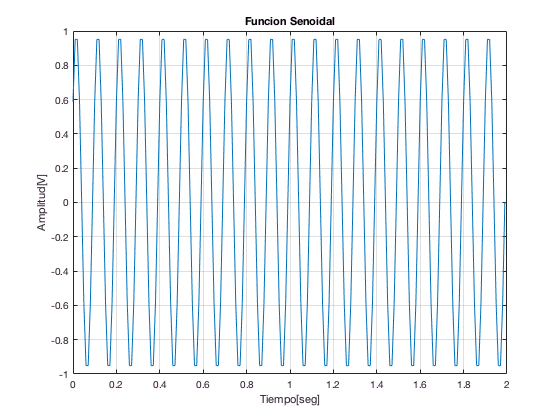

figure(1); set(gcf,'Name','Ejercicio'); 
plot(temp,signal);
title('Funcion Senoidal'); 
xlabel('Tiempo[seg]'); ylabel('Amplitud[V]'); grid;

## Declaro vector de frecuencia

f=0:fs/N:(N-1)*fs/N;


## Realizo la Transformada de Fourier Discreta

signalFFT = fft(signal);

# La consigna es cambiar: fft(signal) por Mi_fft(signal), siendo la expresión de la misma:

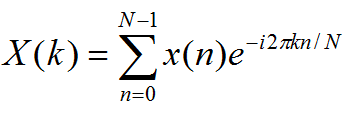

## Ploteo de espectro

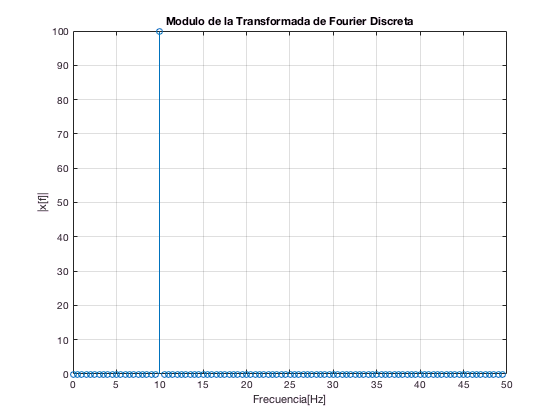

stem(f(1:length(signalFFT)/2),abs(signalFFT(1:length(signalFFT)/2)));
title('Modulo de la Transformada de Fourier Discreta'); 
xlabel('Frecuencia[Hz]'); ylabel('|x[f]|'); grid;